# Create GCP and Metabolomics Ratio Datasets

**Author**: Scott Campit

## Summary

## Load up data

This code block loads up data for ratios of histone markers and metabolites. Note that the ratios were computed using these two Python notebooks:

- **Histone ratios:** https://colab.research.google.com/drive/1v0pFDjc1WLWNDOz152SiK4_TXeICZvUC?usp=sharing

- **Metabolite ratios:** https://colab.research.google.com/drive/1l6leOlZYSfxwUNZwV5tyTVb4_vsaRwms?usp=sharing

clear all; 

GCPFilePath = '~/Data/Proteomics/CCLE/CCLE Global Chromatin Profiles.xlsx';
GCP = readcell(GCPFilePath, ...
                "FileType", "spreadsheet", ...
                "Sheet", 'All Ratios');
            
MetFilePath = '~/Data/Metabolomics/CCLE/CCLE_ALL_Ratios.csv';
MET = readcell(MetFilePath);

#### Keep chromatin marker and metabolite identifiers

First get chromatin markers and metabolite identifiers.

% IDs
chromatin_markers = string(GCP(1, 2:end));
metabolites       = string(MET(1, 2:end));

#### Get cell line intersection between datasets

Next, get the intersection between both datasets based on cancer cell lines.

% Map data based on intersection
[~, ia, ib] = intersect(string(GCP(:, 1)), string(MET(:, 27)));
GCP = GCP(ia, :);
MET = MET(ib, :);

#### Remove unnecessary string identifiers

Finally, remove string identifiers from the dataset.

% Remove cell line identifiers
GCP(:, 1)  = [];
MET(:, [1, 27, 28]) = [];

#### Ensure all data types are double

Convert all data to the same datatype double.

% GCP datasets
GCP = string(GCP);
GCP = str2double(GCP);

% Metabolomics datasets
MET = string(MET);
MET = str2double(MET);

#### Ensure the distributions are about Gaussian.

To ensure that the data distribution is approxomiately normal, I performed quantile normalization and visualized the resulting processed data as a histogram.

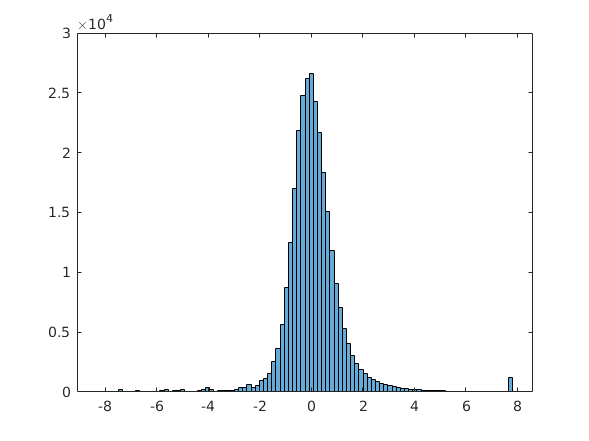

GCP_norm = GCP;
histogram(GCP, 100);

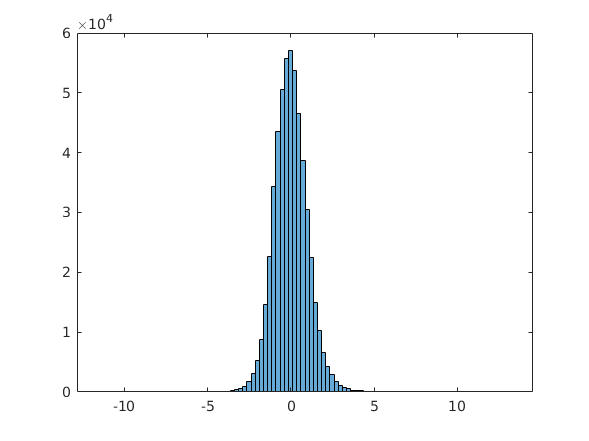

MET_norm = quantilenorm(zscore(MET));
histogram(zscore(MET), 100);

#### Remove all non-finite values

We'll set all NaNs to be 0.

% Set the training size and the random number generator for the
% trainTestSplit function.
GCP_norm(isnan(GCP_norm)) = 0;
MET_norm(isnan(MET_norm)) = 0; 

### Prepare data for running on Great Lakes Cluster

Because the ratio models will take a lot of computational effort and time, I need to run them on Great Lakes. Thus, I have saved the data as a `.mat` file to simplify the preprocessing and loading function. Additionally, I have only included variables that are needed to run the `regressorEnsemble.mlx` function.

save('~/Data/Models/Ratios/Ratio_data.mat');